# Model-Based Security Threat and Risk Analysis - Validation

At this point, we have identified threats, evaluated their risks, and defined countermeasures where the risk was unacceptably high. The next step would be the development of countermeasure(s). However, before we handover the security goals to the engineers, we want to make sure that our threat and risk model is valid, in particular that:

- We have identified at least one threat for each asset (notion of completeness),

- no threat is unreviewed,

- countermeasures have been allocated when the risk is too high,

- requirements (security goal) have been created and linked to the countermeasure(s),

- and there are no broken links between threats, assets, models and safety analysis.

## Preparation

As we want to validate our overall threat and risk model, we need to make sure that all analysis spreadsheets are open. They should been already open from the previous step, however, to make sure they are, [click here](matlab:openSecurityAnalysis).

## Validate Analysis Spreadsheets

### Validate Spreadsheets Manually One-by-One

As we have shown in previous steps of this tutorial (see section "Final Result and Validation" in [defining security goals and countermeasures](matlab:open('Tutorial_Step05_SecurityGoal'))), we can run a *validation* function for each analysis spreadsheet. This is going to check for errors and warnings and annotate the table accordingly. To run it, click on dropdown arrow on the **Analyze Spreadsheet** button in the toolstrip, select the *validation* function and then click on the **Analyze Spreadsheet** button.

Once the analysis has finished, the users only needs to look at the column **"OK?"**, and perform the corrective action (see What is missing? for examples on this).

### Validate all Spreadsheets Automatically

The process described above can of course be done programmatically, and across all the analysis spreadsheet. This produces a summary as evidence that our threat and risk model is valid. To run the validation process across all the analysis spreadsheets, [click here](matlab:tara.functions.validateAllSheets) or run the command below:

tara.functions.validateAllSheets()

You get a bar chart:

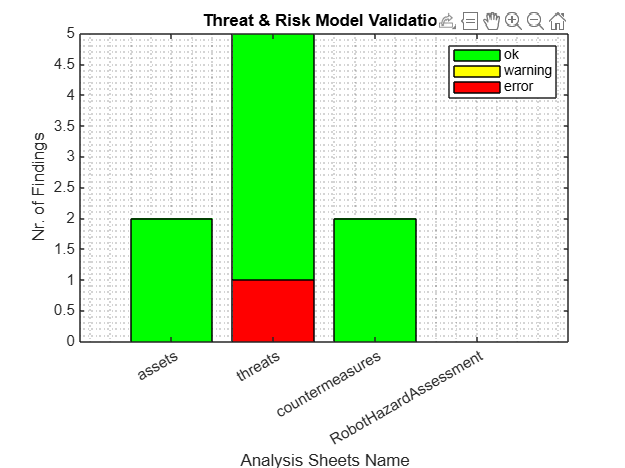

The chart shows one stacked bar for each sheet, which counts the number of rows with errors, warnings and complete ones. If you then want to inspect them in more detail, simply open the respective spreadsheet, and follow the red/green/yellow icons. For example, from the chart above we see that the threats spreadsheet has 1 error. To inspect the details, open the [threats sheet](matlab:open('threats.mldatx')) and locate the row with the error, then find the column with the error and hover over it with the mouse cursor:

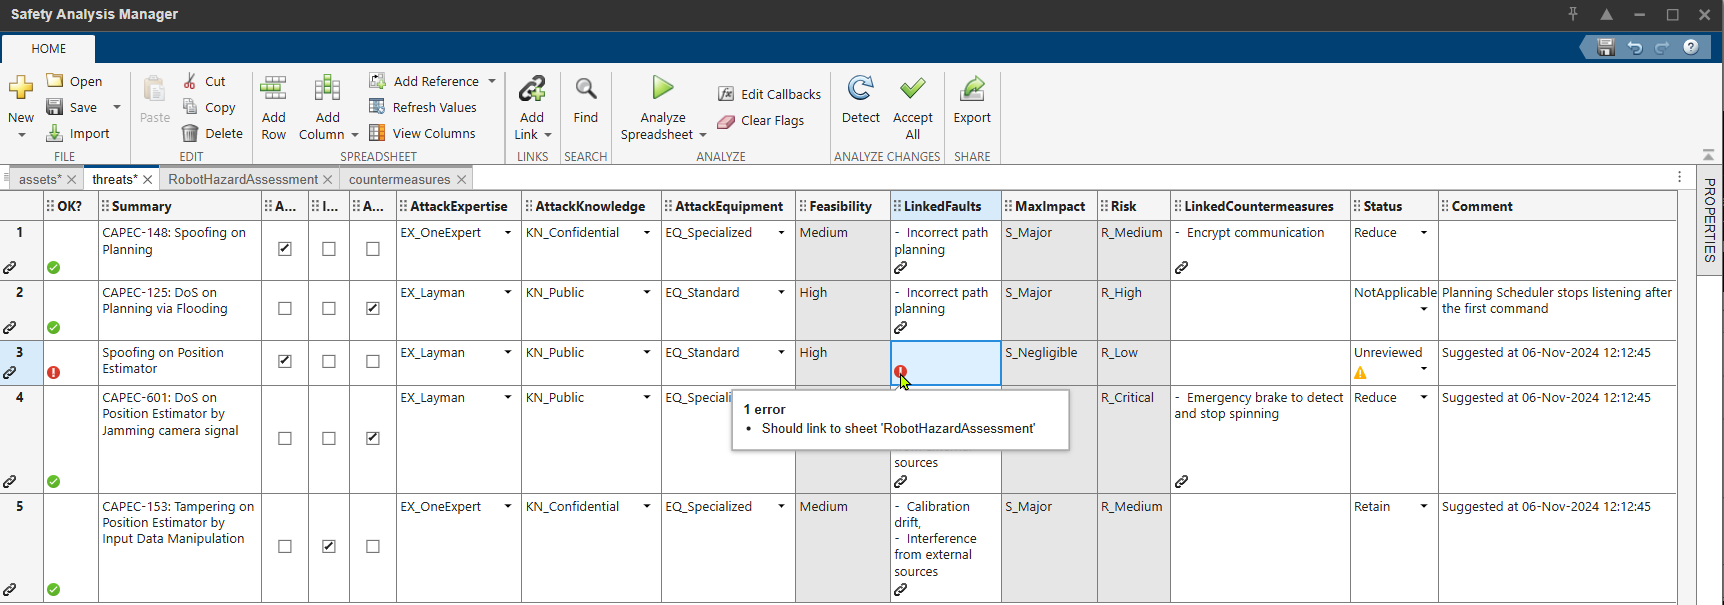

## What's missing?

From the validation checks, we can see the following:

Threats:

- one threat is lacking countermeasures (CAPEC-601: DoS on Position Estimator)

- one threat is unreviewed (Spoofing on Position Estimator)

Assets:

- Complete and consistent w.r.t. risk/threat model.

Countermeasures:

- Complete and consistent w.r.t. risk/threat model.

## What's Next?

Before you go to next steps [click here](matlab:saveAll()) to save all artifacts.

We continue with [implementing countermeasures](matlab:open('Tutorial_Step07_Countermeasure')) or go back to the [overview page](matlab:open('Tutorial')).